Note: to vary omega and t_Vmax, select the desired vector element for the input arguments to ode45

Setup:

%Initial conditions & parameters
S_t0 = 331500000; %population from paper
I_t0 = 1;
R_t0 = 1;
U_t0 = 1;
t0 = 7; % 7 March 2020
t_end = [472, 671]; % june 15 2021 last day of reported cases old, jan 1 2022 is second

%file paths
cases_per_day_path = '/MATLAB Drive/MAT292 Project/cases_per_day_2020_2023.csv';
vaccinations_path = '/MATLAB Drive/MAT292 Project/cleaned_both_vaccinations.csv';

daily_cases = load_cases_from_csv(cases_per_day_path);
CS = create_CS(daily_cases, t_end(2));
t_span1 = [t0, t_end(1)];
t_span2 = [t0, t_end(2)]; %jan 1 2022

%from Dec14 2020 to June 15 2021
v_daily = load_daily_vaccination_from_csv(vaccinations_path);
CV = load_cumulative_vaccination_from_csv(vaccinations_path);

v1 = 0.25/7; % rate of recovery from infection
v2 = 0.75/7; % rate of transition from infected to uninfected
eta = 1/7; % rate of loss of immunity

omega = [0.03, 0.025, 0.02, 0.015];

initial_conditions = [S_t0, I_t0, R_t0, U_t0]; % Initial conditions vector
t_Vmax = [621, 605, 588]; % 90, 85, 80 percent population vaccinated

Solve ODE and Plot Model Projection:

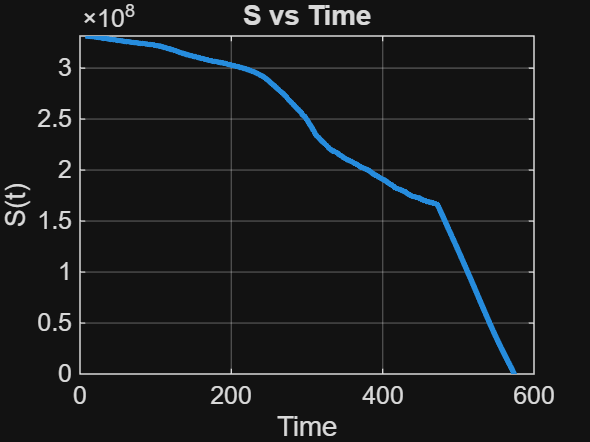

[t1, y1] = ode45(@(t, y) SIRU_ode_func(t, y, v1, v2, eta, CS, omega(1), ...
    initial_conditions, t_Vmax(1), v_daily, CV), t_span2, initial_conditions);

%plot compartments

%plot S on seperate plot since large magnitude differnece
figure;
plot(t1,y1(:,1),'LineWidth', 2) 
ylim([0, inf]);
xlabel('Time');
ylabel('S(t)');
title('S vs Time');
grid on;

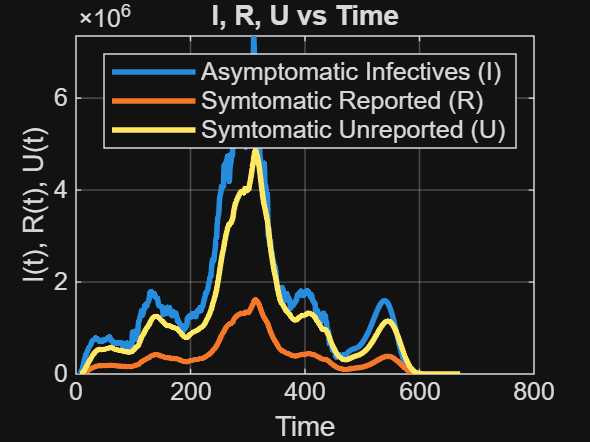


figure;
plot(t1,y1(:,2),'LineWidth', 2)
ylim([0, inf]);
hold on;
plot(t1,y1(:,3),'LineWidth', 2)
plot(t1,y1(:,4),'LineWidth', 2) 
xlabel('Time');
ylabel('I(t), R(t), U(t)');
title('I, R, U vs Time');
legend({'Asymptomatic Infectives (I)','Symtomatic Reported (R)', 'Symtomatic Unreported (U)'}, ...
       'Location', 'northeast', 'FontSize', 9)
grid on;
hold off;

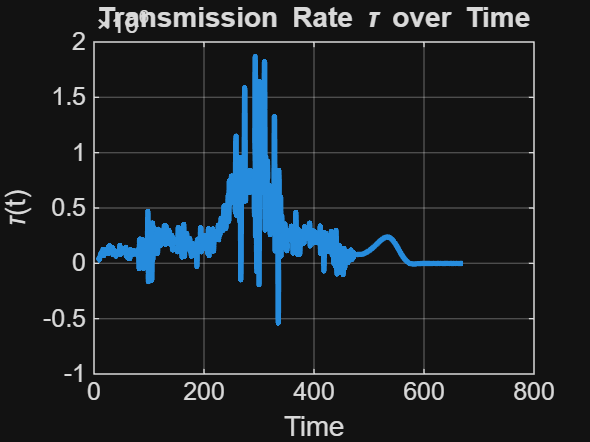


% calculate and predict transmission rate and daily reported rate 
tau_vals = zeros(length(t1), 1);
DR_vals = zeros(length(t1), 1); 
total_daily_cases = zeros(length(t1), 1); 
for i = 1:length(t1)
    S = y1(i, 1);
    I = y1(i, 2); 
    R = y1(i, 3);
    tau_vals(i) = tau_function(t1(i), CS, v1, v2, omega(1), S, I, R);
    DR_vals(i) = v1 * I;
    total_daily_cases(i) = 1/7*I;
end


%plot transmission rate over time
figure;
plot(t1(1:end), tau_vals(1:end), 'LineWidth', 2);
xlabel('Time');
ylabel('\tau(t)');
title('Transmission Rate \tau over Time');
grid on;

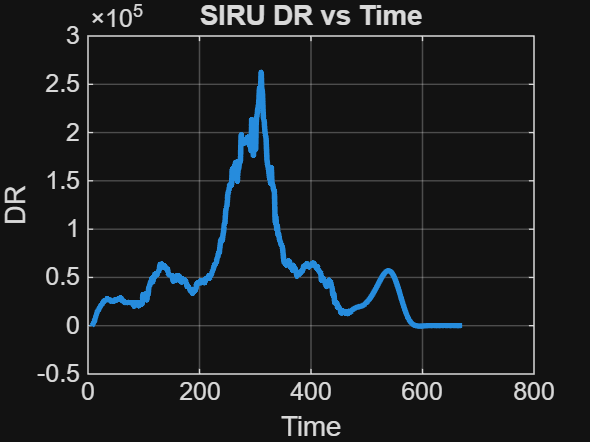


%plot daily reported cases over time
figure;
plot(t1(1:end), DR_vals(1:end), 'LineWidth', 2);
xlabel('Time');
ylabel('DR');
title('SIRU DR vs Time');
grid on;

MAE Error calculation:

[mae, errors, y1_discrete] = calculate_mae(t0, 600, CS, t1, DR_vals);

MAE Calculation Summary:
  Data points: 594
  MAE: 15171.018639
  Range of actual data: [1934.4286, 250772.4286]
  Range of solver data: [-373.8182, 257628.6300]


ODE System and Additional Funcitons:

function dydt = SIRU_ode_func(t, y, v1, v2, eta, CS, omega, initial_conditions, t_Vmax, v_daily, CV)
    %ode system
    S = y(1);
    I = y(2);
    R = y(3);
    U = y(4);

    S_0 = initial_conditions(1);
    I_0 = initial_conditions(2);
    R_0 = initial_conditions(3);
    U_0 = initial_conditions(4);

    tau_val = tau_function(t, CS, v1, v2, omega, S, I, R);
    v = v_function(t, v_daily, CV, S, S_0, t_Vmax);

    dSdt = -tau_val - v * S;
    dIdt = tau_val - (v1 + v2) * I;
    dRdt = v1 * I - eta * R;
    dUdt = v2 * I - eta * U;
    
    dydt = [dSdt; dIdt; dRdt; dUdt];
end

function tau_val = tau_function(t, CS, v1, v2, omega, S, I, R)
    %transmission rate
    t_D = 472; % 472 is June 15 2021, data has extra day of cases; 
                % from this website https://www.timeanddate.com/date/durationresult.html?m1=3&d1=1&y1=2020&m2=10&d2=1&y2=2021&ti=on
    t1 = 488;
    t2 = 580;

    tau_D = 44188;

    S_D = 109931000;
    I_D = 339353;
    R_D = 101039;
    U_D = 303117;


    if t <= t_D
        %CS at t
        CS_t = ppval(CS, t);
        
        %CS' at t
        CS_deriv = fnder(CS, 1);
        CS_prime_t = ppval(CS_deriv, t);
        
        %CS'' at t
        CS_deriv2 = fnder(CS, 2);
        CS_double_prime_t = ppval(CS_deriv2, t);
        
        tau_val = (CS_double_prime_t + CS_prime_t) / v1 + (v1 + v2) * (CS_prime_t + CS_t) / v1;
    elseif t <= t1 %July 1 2021
        tau_val = tau_D*((I+4*R)*S)/((I_D + 4*R_D)*S_D);
    elseif t <= t2
        tau_val = (1 + omega*(t - t1))*(tau_D)*((I+4*R)*S)/((I_D + 4*R_D)*S_D);
    else
        tau_val = (1 + omega*(t2 - t1))*(tau_D)*((I+4*R)*S)/((I_D + 4*R_D)*S_D);
    end
end

function v = v_function(t, v_daily, CV, S, S_0, t_Vmax)
%vaccination factor
    t1 = 288; % dec13 2020, one day before 14th when vaccine start
    t2 = 472; %june15 2021, last day of NOT constant vaccine

    index = floor(t - t1);

    if t <= t1 || index == 0
        v_daily_t = 0;
        CV_t = 0; 

    elseif t <= t2
        v_daily_t = v_daily(index);
        CV_t = CV(index); 

    elseif t <= t_Vmax
        v_daily_t = 1000000;
        CV_t = CV(end) + (t - t2) * 1000000;
    else
        v_daily_t = 0;
        CV_t = 0; 
    end
    v = 0.95 * v_daily_t / (S_0 - CV_t);
end

function CS = create_CS(daily_cases, t_end)
%take daily reported cases from CDC and create spline of weekly rolling
%averages
    weekly_avg = movmean(daily_cases, 7);
    weekly_avg = weekly_avg(1:t_end);
    t_integer = 1:length(weekly_avg);
    CS = spline(t_integer, weekly_avg);
end

function daily_cases = load_cases_from_csv(filename)
%pull daily cases from csv
    data = readtable(filename, 'Delimiter', ',');
    daily_cases = data{:, 2};
end

function v_daily = load_daily_vaccination_from_csv(filename)
%pull daily vaccinations from csv
    data = readtable(filename, 'Delimiter', ',');
    v_daily = data{:, 3}; 
end

function CV = load_cumulative_vaccination_from_csv(filename)
%pull commulative vaccinations from csv
    data = readtable(filename, 'Delimiter', ',');
    CV = data{:, 2}; 
end

function [mae, errors, y1_discrete] = calculate_mae(t0, t_end, CS, t_solver, y_solver)
%compare spline daily cases of actual cases (7 day rolling average) vs ode
%prediction

    %get discrete points
    t_discrete = t0:1:t_end;

    CS_discrete = ppval(CS, t_discrete);
    CS_discrete = CS_discrete(:);
    
    y1_discrete = interp1(t_solver, y_solver, t_discrete, 'linear', 'extrap');
    y1_discrete = y1_discrete(:); %make same orientation

    errors = abs(CS_discrete - y1_discrete);
    mae = mean(errors);
    
    % Display summary
    fprintf('MAE Calculation Summary:\n');
    fprintf('  Data points: %d\n', length(t_discrete));
    fprintf('  MAE: %.6f\n', mae);
    fprintf('  Range of actual data: [%.4f, %.4f]\n', min(CS_discrete), max(CS_discrete));
    fprintf('  Range of solver data: [%.4f, %.4f]\n', min(y1_discrete), max(y1_discrete));
end